% System: Trajectory tracking
clear;
Ac = [-0.313 56.7 0;-0.0139 -0.426 0;0 56.7 0];
Bc = [0.232;0.0203;0];
Cc = [0 0 1];
Dc = zeros(size(Cc,1),size(Bc,2));

Ts = 0.02; %Probably in seconds

sys_c = ss(Ac,Bc,Cc,Dc);
sys = c2d(sys_c,Ts);

[A,B,C,D] = dssdata(sys)

A =     0.9936    1.1256         0
   -0.0003    0.9914         0
   -0.0002    1.1291    1.0000


B =     0.0049
    0.0004
    0.0002


C =      0     0     1


D = 0


safex = [0.3;0.3;1.5];
depth = 0.1;

size_x = [size(A,2) 1];
size_y = [size(C,1) 1]; 


%p = 500; 
%Q = p*C'*C;
%Q = zeros(size(A));
%R = zeros(size(C,1),size(C,1)); 
% Q = [ 0.5 0 0 ;
%       0 0.1 0;
%       0 0 0.12;
%     ];

% Q = [ 0.3 0 0 ;
%       0 0.5 0;
%       0 0 0.12;
%     ];
% 
% R = 0.001;


Q = [ 30 0 0 ;
      0 50 0;
      0 0 12;
    ];

R = 0.1;
R = R*Ts*Ts;
Q = Q*Ts*Ts;
[K] = lqrd(Ac,Bc,Q,R,Ts)

K =     8.3717  252.4861   10.1774


[Kc] = lqr(sys_c,Q,R)

Kc =     9.0774  261.3949   10.9545


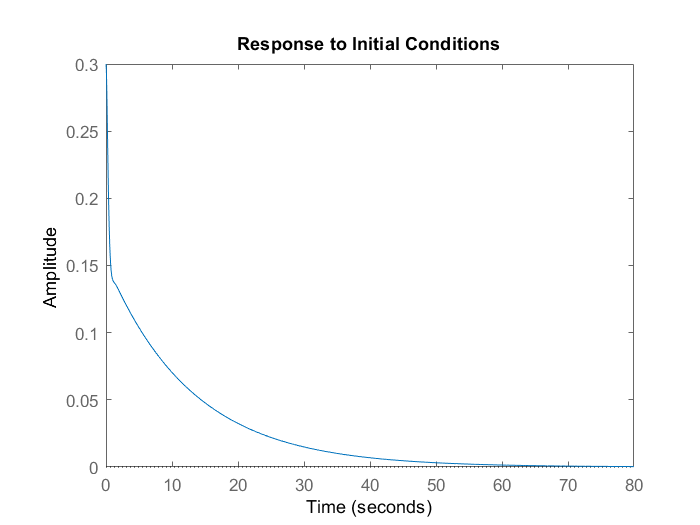

sys_gain_c = ss(Ac-Bc*Kc,Bc,Cc,Dc);

QN = 1;
RN = 10;
sys_gain = ss(A- B*K,B,C,D,Ts);
[kalmf,L,P] = kalman(sys,QN,RN);
[kalmf_gain,L_gain,P_gain] = kalman(sys_gain,QN,RN);


x0 = depth*safex;
x0 = [0; 0; 0.3];
initial(sys_gain_c,x0);

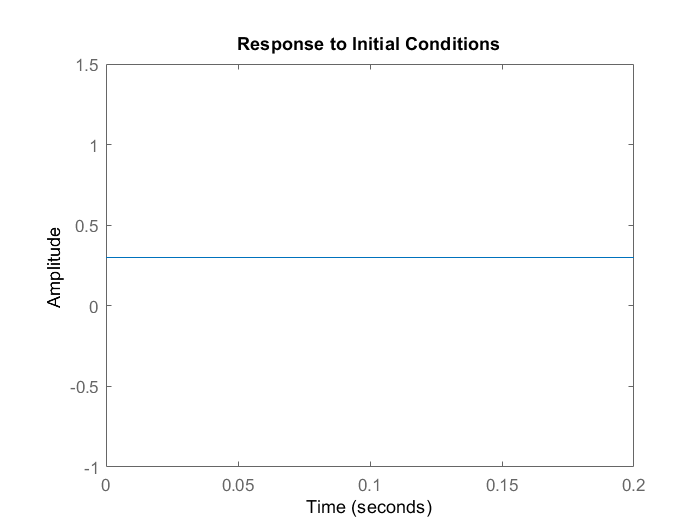


initial(sys_c,x0);